# Metodi d'integrazione numerica semplice

## Introduzione

L'integrazione numerica permette il **calcolo dell'integrale**, quella parte di grafico sottostante la curva. Ci sono casi non triviali per cui il calcolo della primitiva non è immediato per ragioni di complessità e quindi costo computazionale e tempo. I metodi d'integrazione numerica servono a semplificare il problema, cercando di approssimare l'integrale limitato nel modo più prossimo al valore esatto.

Ogni **formula di quadratura** è adatta per l'approssimazione di funzioni di tipo diverso, in particolare, il **grado di esattezza** di una formula indica quali integrali la formula stessa riesce ad approssimare senza alcun errore. La regola generale che segue descrive la precisione di una formula


$$\begin{array}{l}
Q_n \left\lbrack f\right\rbrack \to n+1\;\;\;\;\;\;\;\;\textrm{se}\;\;\;\;\;\;\;\;n\;\textrm{pari}\\
\;\;\;\;\;\;\;\;\;\;\;\;\to n\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\textrm{se}\;\;\;\;\;\;\;\;n\;\textrm{dispari}
\end{array}$$


Le formule che vediamo sono dette **formule di Newton-Cotes** e prevedono l'uso di **punti d'integrazione equispaziati** tra loro.

### Formula del punto medio


$$\int_a^b f\left(x\right)\;\mathrm{dx}\cong f\left(\frac{a+b}{2}\right)\left(b-a\right)\;\;\;\;\;\;\;\;Q_1 \left\lbrack f\right\rbrack$$


La formula del punto medio (o rettangolo) divide il grafico in due metà e approssima l'integrale sulle due metà del singolo rettangolo. Questa formula ha **grado di esattezza 1** perché approssima esattamente solo le funzioni di quel grado o inferiore. Per generalizzare, questa formula integra esattamente funzioni della forma $f\left(x\right)\equiv C$ o della forma $f\left(x\right)=\alpha x+\beta$. Vediamo un esempio usando il comando `integral` come valore di controllo.

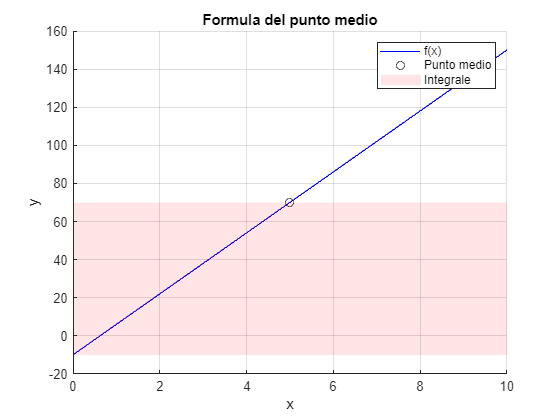

f = @(x) 16*x - 10;

a = 0; b = 10;

x = linspace(a, b, 1000);

% int = (b - a) % larghezza intervallo
mp = (a + b) / 2; % punto medio

figure; hold on; grid on
xlabel('x'); ylabel('y')
title('Formula del punto medio')
plot(x, f(x), 'b-', 'DisplayName', 'f(x)')
plot(mp, f(mp), 'ko', 'DisplayName','Punto medio') % visualizzazione punto medio
legend

% Visualizzazione integrale su grafico
x_rect = [a, b, b, a];
y_rect = [min(f(x)), min(f(x)), f(mp), f(mp)];
fill(x_rect, y_rect, 'r', 'FaceAlpha', 0.1, 'EdgeColor', 'none', 'DisplayName', 'Integrale');


integral(f, a, b)

ans =    700


punto_medio(f, a, b)

ans =    700


### Formula del trapezio


$$\int_b^a f\left(x\right)\;\textrm{dx}\cong \left(f\left(a\right)+f\left(b\right)\right)\left(\frac{b-a}{2}\right)\;\;\;\;\;\;\;\;Q_1 \left\lbrack f\right\rbrack$$


La formula del trapezio crea una zona di area che non più pare rettangolare ma trapezoidale. Questa caratteristica permette d'integrare meglio le curve. Cio nonostante, come per la formula del punto medio, questa ha **grado di esattezza 1**.

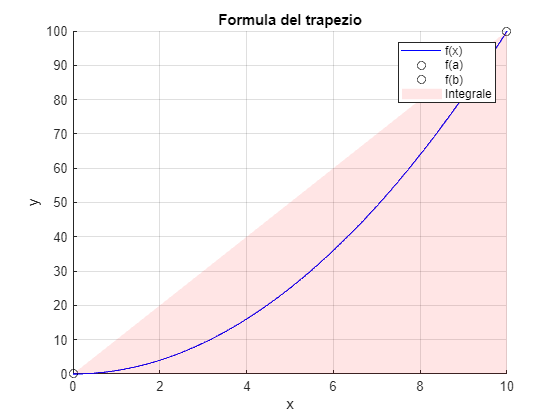

f = @(x) x.^2;

a = 0; b = 10;

x = linspace(a, b, 1000);

figure; hold on; grid on
xlabel('x'); ylabel('y')
title('Formula del trapezio')
plot(x, f(x), 'b-', 'DisplayName', 'f(x)')
plot(a, f(a), 'ko', 'DisplayName', 'f(a)')
plot(b, f(b), 'ko', 'DisplayName', 'f(b)')
legend

x_rect = [a, b, b, a];
y_rect = [min(f(x)), max(f(x)), min(f(x)), min(f(x))];
fill(x_rect, y_rect, 'r', 'FaceAlpha', 0.1, 'EdgeColor', 'none', 'DisplayName', 'Integrale');


q0 = integral(f, a, b)

q0 =      3.333333333333334e+02


q1 = trapezio(f, a, b)

q1 =    500


### Formula di Cavalieri-Simpson


$$\int_b^a f\left(x\right)\;\textrm{dx}\cong \frac{b-a}{6}\left\lbrack f\left(a\right)+4f\left(\frac{a+b}{2}\right)+f\left(b\right)\right\rbrack \;\;\;\;\;\;\;\;Q_2 \left\lbrack f\right\rbrack$$


A differenza delle altre formule viste, questa ha **grado di esattezza 3**, il che significa che riesce a integrare funzioni con quel grado massimo. Questa formula utilizza un polinomio interpolatore passante per tre punti per integrare esattamente le curve.

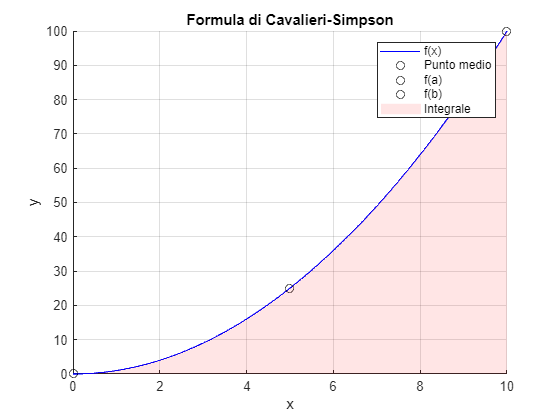

f = @(x) x.^2;

a = 0; b = 10;

X = linspace(a, b, 1000);

x = linspace(a, b, 3);
y = f(x);

figure; hold on; grid on
xlabel('x'); ylabel('y')
title('Formula di Cavalieri-Simpson')
plot(X, f(X), 'b-', 'DisplayName', 'f(x)')
plot(mp, f(mp), 'ko', 'DisplayName', 'Punto medio')
plot(a, f(a), 'ko', 'DisplayName', 'f(a)')
plot(b, f(b), 'ko', 'DisplayName', 'f(b)')
legend

xi = [x(1) x(2) x(3)];
yi = [y(1) y(2) y(3)];
x_fill = linspace(x(1), x(end), 100);
y_fill = f(x_fill);
fill([x_fill x(end) x(1)], [y_fill 0 0], 'r', 'FaceAlpha', 0.1, 'EdgeColor', 'none', 'DisplayName', 'Integrale');


q0 = integral(f, a, b)

q0 =      3.333333333333334e+02


q1 = cavalieri_simpson(f, a, b)

q1 =      3.333333333333333e+02


# Metodi d'integrazione numerica composita

## Introduzione

I metodi d'integrazione numerica composita si fanno in modo simile ai metodi semplici con la differenza che **i nodi equispaziati vengono aumentati di un numero arbitrario **$\mathit{\mathbf{m}}$. Questo permette di **aumentare la precisione** dei metodi di quadratura al loro limite sempre tenendo conto del fatto che alcuni meglio si adattano a funzioni piuttosto che altri. Da notare che aumentare il grado del polinomio interpolatore per nodi equispaziati non è la strategia vincente per approssimare meglio l'integrale.

Le formule del punto medio composite hanno lo stesso grado di esattezza delle controparti semplici.

### Formula del punto medio composita


$$H\sum_{i=1}^m \left\lbrack f\left(\frac{x_i +x_{i-1} }{2}\right)\right\rbrack \;\;\;\;\;\;\;\;H=\frac{b-a}{m}$$


La formula composita del punto medio aumenta il numero di rettangoli per un numero arbitrario $m$. La lunghezza degli intervalli è la parte cruciale delle formule composite, la variabile $\mathit{\mathbf{H}}$ indica la **lugnhezza di ogni singolo intervallo** (equispaziati). Alcune note sulla formula:

- il concetto rimane uguale come nella forma semplice, l'intervallo viene separato a metà per ciascuna $x$ ascissa dei nodi scelti;

- l'indice della sommatoria parte da 1 siccome i termini all'interno della divisione prevedono di usare l'elemento di indice precedente.

q = H * sum(f((x(1:mp)/x(2:m+1))/2));

Unrecognized function or variable 'H'.

### Formula del trapezio composita


$$\frac{H}{2}\left\lbrack f\left(x_0 \right)+\sum_{i=1}^{m-1} f\left(x_i \right)+f\left(x_m \right)\right\rbrack \;\;\;\;\;\;\;\;H=\frac{b-a}{m}$$


La formula composita del trapezio aumenta il numero di trapezi per un numero arbitrario $m$. Alcune note sulla formula:

- il primo punto e l'ultimo punto vengono separati dalla sommatoria in quanto termini iniziali e finali del poligono formato dalla somma dei trapezi;

- la sommatoria parte da 1 e arriva a $m-1$ per via dell'omissione del primo punto e ultimo punto.

q = (H/2) * (f(x(a)) + sum(f(x(2:m))) + f(b));

### Formula di Cavalieri-Simpson composita


$$\frac{H}{6}\sum_{i=1}^m \left\lbrack f\left(x_i \right)+4f\left(\frac{x_i +x_{i-1} }{2}\right)+f\left(x_{i-1} \right)\right\rbrack \;\;\;\;\;\;\;\;H=\frac{b-a}{m}$$


La formula composita di Cavalieri-Simpson è la migliore per l'approssimazione d'integrali. Il polinomio interpolatore della formula è costituito da un numero arbitrario di nodi $m$. Alcune note sulla formula:

- il punto precedente e il punto successivo sono i nodi che definiscono l'inizio e la fine di ciascun polinomio interpolatore;

- la sommatoria rappresenta i nodi intermediari al nodo di partenza e al nodo finale.

- l'indice della sommatoria parte da 1 siccome i termini all'interno della divisione prevedono di usare l'elemento di indice precedente.

q = (H/6) * sum(f(x(1:m)) + 4*f((x(1:m)+x(2:m+1))/2) + f(x(2:m+1)));

## Errore

Il comando `integral` calcola la soluzione di un integrale limitato usando formule di *quadratura adattive*, basandosi su criteri come lo scostamento del valore quasi-piatto della funzione o il suo variamento sporadico con conseguente aumento del numero di intervalli. Le nostre formule di quadratura possono aumentare di precisione aumentando il numero di intervalli.

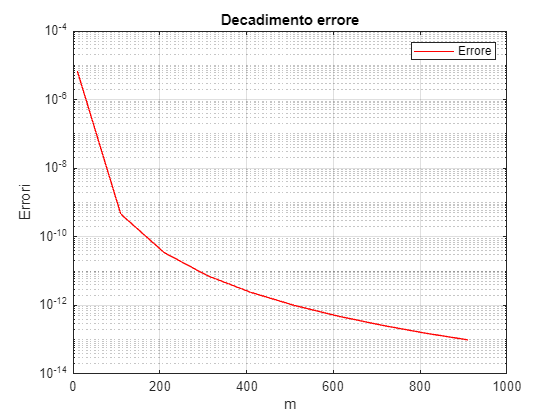

f = @(x) sin(x); % Integrale esatto [0,pi] è 2

a = 0; b = 3.141592653589793;

q0 = integral(f, a, b); % Valore esatto

m = 10:100:1000; % Numero intervalli
q = zeros(1,length(m)); % Vettore integrali approssimati
e = zeros(1,length(m)); % Vettore errori

for i = 1:length(m)
    q(i) = cavalieri_simpson_composita(f, a, b, m(i));
    e(i) = abs(q0 - q(i));
end

figure;
semilogy(m, e, 'r-', 'DisplayName', 'Errore')
hold on; grid on
xlabel('m'); ylabel('Errori')
title('Decadimento errore')
legend

Possiamo visualizzare l'errore stampando una tabella che prende il nome di **tabella del decadimento dell'errore**.

table(m', e', 'VariableNames', {'Numero Intervalli', 'Errore'})

ans = 10×2 table
    Numero Intervalli      Errore  
    _________________    __________

            10           6.7844e-06
           110           4.6204e-10
           210           3.4784e-11
           310            7.325e-12
           410           2.3943e-12
           510           1.0003e-12
           610           4.8916e-13
           710           2.6668e-13
           810           1.5654e-13
           910            9.881e-14
